Example of UTS*Area load cases 

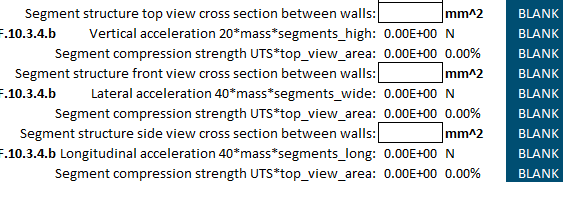

Battery Coverved Volume dimensions(what area the casing must enclose)

SegLength = 23*0.985*25.4/1000;%num modules*moduleDepth*mmtoinches
SegWidth = 3.15*25.4/1000;%width(ex:65mm(cell)+module sides)
SegHeight = 5*25.4/1000;%height(m)
ModuleWeight = 317/1000;%weight in kg
SegmentWeight = ModuleWeight*23;
CasingThickness = 1/8*25.4/1000;

TopCrossSecArea = SegLength*CasingThickness*2

TopCrossSecArea = 0.0037

TopCrossSecForce = SegmentWeight*20*9.8%in newtons

TopCrossSecForce = 1.4290e+03

TopStress = TopCrossSecForce/TopCrossSecArea

TopStress = 3.9109e+05


WidthCrossSecArea = SegLength*CasingThickness*2

WidthCrossSecArea = 0.0037

WidthCrossSecForce = 6*SegmentWeight*40*9.8%in newtons

WidthCrossSecForce = 1.7148e+04

WidthStress = WidthCrossSecForce/WidthCrossSecArea

WidthStress = 4.6930e+06



DepthCrossSecArea = SegWidth*CasingThickness*2 + SegHeight*CasingThickness*2;
DepthCrossSecForce = SegmentWeight * 40 * 9.8;
DepthStress = DepthCrossSecForce/DepthCrossSecArea

DepthStress = 2.1742e+06

Bolt calculations

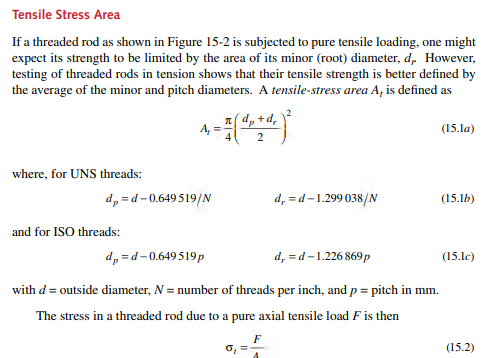

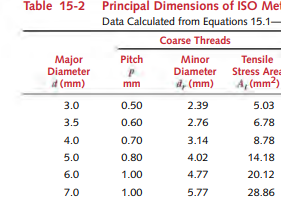

 dia = 6;
 pitch = 1;
diaPitch = dia - 0.649519*pitch;%mm 
diaRoot = dia - 1.226869*pitch ;%mm
AreaBoltTensile = pi/4*((diaPitch+diaRoot)/2)^2;%in mm^2
ABTMeters = AreaBoltTensile/1000000

ABTMeters = 2.0123e-05


exampleGr5Tensile = 827370875%pa 

exampleGr5Tensile = 827370875

MaxForce = exampleGr5Tensile*ABTMeters %newtons

MaxForce = 1.6649e+04

Tear out calcs

garolite
BoltDistanceFromEdge = 10/1000;% possible realistic distance from edge
minBoltDisFromEdge = 1;